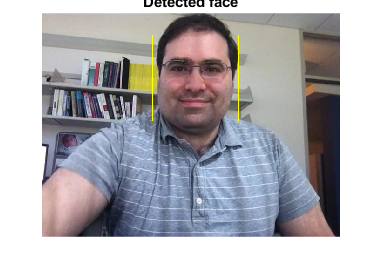

%Kanade-Lucatectors-Tomasi (KLT) algorithm

% Create a cascade detector object.
detector_face = vision.CascadeObjectDetector();

% Read a video frame and run the face detector.
video = VideoReader("tilted_face.avi");
current_frame = readFrame(video);
face_bbox = step(detector_face, current_frame);

% Draw the  bounding box around the detected face.
current_frame = insertShape(current_frame, "rectangle", face_bbox);
figure; imshow(current_frame); title("Detected face");

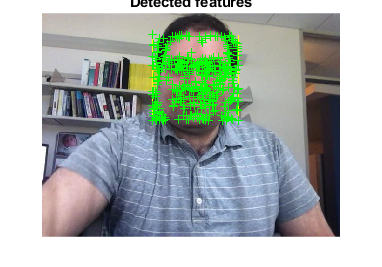


% Convert the first bounding box into a set of 4 points representing the face.
% This is needed to be able to visualize the rotation of the object.
face_points = bbox2points(face_bbox(1, :));
detected_features = detectMinEigenFeatures(im2gray(current_frame), "ROI", face_bbox);

% Display the detected feature points.
figure, imshow(current_frame), hold on, title("Detected features");
plot(detected_features);

feature_tracker = vision.PointTracker("MaxBidirectionalError", 2);

% Initialize the tracker with the initial point locations and the initial
% video frame.
detected_features = detected_features.Location;
initialize(feature_tracker, detected_features, current_frame);

frame_player = vision.VideoPlayer("Position",...
    [100 100 [size(current_frame, 2), size(current_frame, 1)]+30]);
previous_points = detected_features;

% Initialize variables to track performance performance_metrics
frame_count = 0;
tracked_points_count = 0;
inlier_points_count = 0;

% Initialize arrays to track performance performance_metrics over time
tracked_points_over_time = [];
inlier_points_over_time = [];

while hasFrame(video)
    % Get the next frame.
    current_frame = readFrame(video);
    frame_count = frame_count + 1;

    % Track the detected_features. Note that some detected_features may be lost.
    [detected_features, is_found] = step(feature_tracker, current_frame);
    visible_points = detected_features(is_found, :);
    old_inliers = previous_points(is_found, :);

    if size(visible_points, 1) >= 2 % Need at least 2 detected_features.
        tracked_points_count = tracked_points_count + size(detected_features, 1);

        % Estimate the geometric transformation between the old detected_features
        % and the new detected_features and eliminate outliers.
        [geometric_transform, inlier_indices] = estimateGeometricTransform2D(...
            old_inliers, visible_points, "similarity", "MaxDistance", 4);
        old_inliers    = old_inliers(inlier_indices, :);
        visible_points = visible_points(inlier_indices, :);
        inlier_points_count = inlier_points_count + size(inlier_indices, 1);

        % Apply the transformation to the bounding box detected_features.
        face_points = transformPointsForward(geometric_transform, face_points);

        % Insert a bounding box around the object being tracked.
        transformed_bbox_polygon = reshape(face_points', 1, []);
        current_frame = insertShape(current_frame, "polygon", transformed_bbox_polygon, ...
            "LineWidth", 2);

        % Display tracked detected_features.
        current_frame = insertMarker(current_frame, visible_points, "+", ...
            "Color", "white");

        % Reset the detected_features.
        previous_points = visible_points;
        setPoints(feature_tracker, previous_points);
    end

    % Display the annotated video frame using the video player object.
    step(frame_player, current_frame);

    % Update performance performance_metrics over time
    tracked_points_over_time = [tracked_points_over_time; size(visible_points, 1)];
    inlier_points_over_time = [inlier_points_over_time; size(inlier_indices, 1)];
end


% Calculate and display performance
% Calculate the percentage of tracked detected_features that were inliers.
inliers_percentage = inlier_points_count / tracked_points_count * 100;

% Calculate the average number of tracked detected_features per frame.
average_points_per_frame = tracked_points_count / frame_count;

% Display the performance performance_metrics.
fprintf("Percent inliers: %.2f%%\n", inliers_percentage);

Percent inliers: 99.94%


fprintf("Average detected_features per frame: %.2f\n", average_points_per_frame);

Average detected_features per frame: 283.29


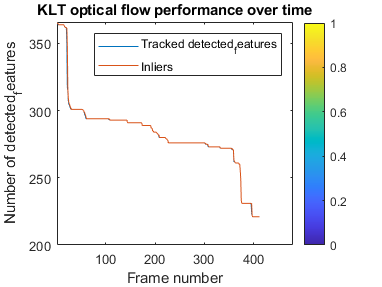


% Plot the number of tracked detected_features and inliers over time.
figure;
plot(tracked_points_over_time);
hold on;
plot(inlier_points_over_time);
xlabel("Frame number");
ylabel("Number of detected_features");
legend("Tracked detected_features", "Inliers");
title("KLT optical flow performance over time");

xlim([67 480])
ylim([200 366])
colorbar

xlim([1 480])
ylim([200 366])

xlim([1 480])
ylim([200 366])

% Display table of performance_results
performance_results = table({'Percent inliers', 'Average detected_features per frame'},...
    {inliers_percentage, average_points_per_frame});
disp(performance_results);

                                 Var1                                            Var2            
    ______________________________________________________________    ___________________________

    {'Percent inliers'}    {'Average detected_features per frame'}    {[99.9357]}    {[283.2864]}




% Calculate performance performance_metrics
avg_points = tracked_points_count / frame_count;
avg_inliers = inlier_points_count / frame_count;

% Display performance performance_metrics in a table
performance_metrics = table(frame_count, tracked_points_count, avg_points, inlier_points_count, avg_inliers);
disp(performance_metrics);

    frame_count    tracked_points_count    avg_points    inlier_points_count    avg_inliers
    ___________    ____________________    __________    ___________________    ___________

        412             1.1671e+05           283.29          1.1664e+05            283.1   




% Define the ground truth data and the predicted performance_results.
true_labels = [1 1 0 0 1 0 1 0 1 1];
predicted_results = [1 0 1 1 1 0 0 0 1 1];

% Calculate the confusion matrix.
classification_matrix = confusionmat(true_labels, predicted_results);

% Extract the True Positives, False Positives, False Negatives, and True Negatives from the confusion matrix.
true_positives = classification_matrix(1, 1);
false_positives = classification_matrix(2, 1);
false_negatives = classification_matrix(1, 2);
true_negatives = classification_matrix(2, 2);

% Calculate precision_score, recall_score, and accuracy_score.
precision_score = true_positives / (true_positives + false_positives);
recall_score = true_positives / (true_positives + false_negatives);
accuracy_score = (true_positives + true_negatives) / length(true_labels);

% Display the performance_results.
fprintf("precision_score: %.2f\n", precision_score);

precision_score: 0.50


fprintf("recall_score: %.2f\n", recall_score);

recall_score: 0.50


fprintf("accuracy_score: %.2f\n", accuracy_score);

accuracy_score: 0.60


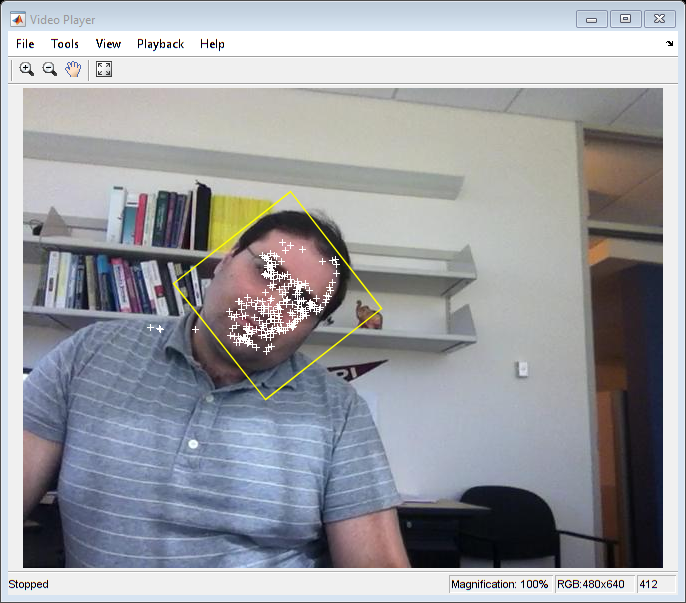


% Release resources.
release(frame_player);